%  An highlighted block
clear all; clc; close all;

## caculate endpoint

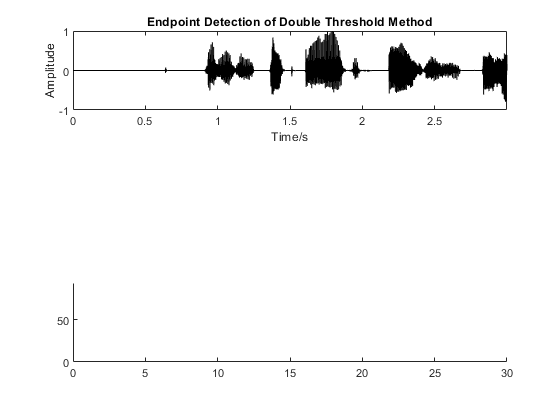

[x,fs]=audioread('C:\Users\Hi\Desktop\LVTN\GUI_matlab\Audio\s11.wav');                    % Read data file
x=x/max(abs(x));                        %  Amplitude normalization
N=length(x);                            %  Take the signal length
time=(0:N-1)/fs;                        %  calculating time 
subplot 311
plot(time,x,'k');         
title('Endpoint Detection of Double Threshold Method');
ylabel('Amplitude'); axis([0 max(time) -1 1]); 
xlabel('Time/s');

subplot(3,1,3)
xlim([0.0 30.0])
ylim([0 94])


wlen=256; 
inc =100;                       %  Framing parameters
IS  =0.1; 
overlap=wlen-inc;               %  Set upIS
NIS=fix((IS*fs-wlen)/inc +1);           %  CalculationNIS
fn=fix((N-wlen)/inc)+1;                 %  Find the number of frames
frameTime=FrameTimeC(fn, wlen, inc, fs);%  Calculate the time corresponding to each frame
[voiceseg,vsl,SF,NF,amp,zcr]=vad_ezm1(x,wlen,inc,NIS);  %  Endpoint detection

Error: Not find endding point!


## plot

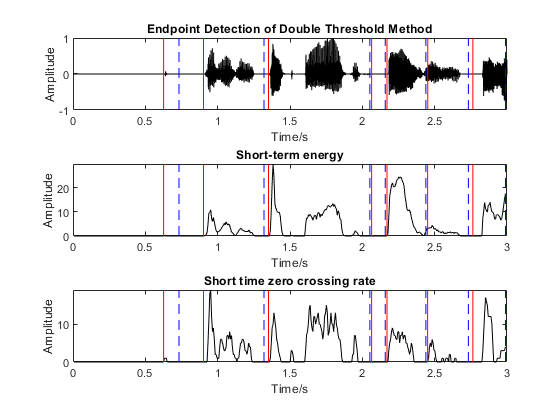

subplot 312
plot(frameTime,amp,'k');         
ylim([min(amp) max(amp)])
title('Short-term energy');
ylabel('Amplitude'); 
xlabel('Time/s');
subplot 313
plot(frameTime,zcr,'k');     
ylim([min(zcr) max(zcr)])
title('Short time zero crossing rate');
ylabel('Amplitude'); 
xlabel('Time/s');

for k=1 : vsl                           %  Draw the starting and ending points
    subplot 311
    nx1=voiceseg(k).begin; nx2=voiceseg(k).end;
    nxl=voiceseg(k).duration;
    line([frameTime(nx1) frameTime(nx1)],[-1.5 1.5],'color','r','LineStyle','-');
    line([frameTime(nx2) frameTime(nx2)],[-1.5 1.5],'color','b','LineStyle','--');
    subplot 312
    line([frameTime(nx1) frameTime(nx1)],[min(amp) max(amp)],'color','r','LineStyle','-');
    line([frameTime(nx2) frameTime(nx2)],[min(amp) max(amp)],'color','b','LineStyle','--');    
    subplot 313
    line([frameTime(nx1) frameTime(nx1)],[min(zcr) max(zcr)],'color','r','LineStyle','-');
    line([frameTime(nx2) frameTime(nx2)],[min(zcr) max(zcr)],'color','b','LineStyle','--');    
end

## Function

function frameTime=FrameTimeC(frameNum,framelen,inc,fs)
%  Calculate the time corresponding to each frame after framing
frameTime=(((1:frameNum)-1)*inc+framelen/2)/fs;
end

function soundSegment=findSegment(express)
if express(1)==0
         voicedIndex=find(express); % Find the position of 1 in express
else
    voicedIndex=express;
end

soundSegment = [];
k = 1;
 soundSegment(k).begin = voicedIndex(1); % Set the starting position of the first group of segments
for i=1:length(voicedIndex)-1,
	 if voicedIndex(i+1)-voicedIndex(i)>1, % This group has a segment end
     soundSegment(k).end = voicedIndex(i); % Set the end position of the segment in this group.
	 soundSegment(k+1).begin = voicedIndex(i+1);% Set the starting position of the next set of segments  
     k = k+1;
    end
end
 soundSegment(k).end = voicedIndex(end); % The last group has the end position of the segment
 % Calculate the length of each segment in a group
for i=1 :k
    soundSegment(i).duration=soundSegment(i).end-soundSegment(i).begin+1;
end

end

function [voiceseg,vsl,SF,NF,amp,zcr]=vad_ezm1(x,wlen,inc,NIS)
 x=x(:);% convert x into a column array
 maxsilence = 15;% initialization
minlen  = 6;    
status  = 0;
count   = 0;
silence = 0;
 
 y=enframe(x,wlen,inc)';% frame
 fn=size(y,2);% number of frames
 amp=sum(y.^2);% Find the short-term average energy
 zcr=zc2(y,fn);% calculate the short-term average zero-crossing rate
 ampth=mean(amp(1:NIS));% Calculate the average value of the energy and the zero-crossing rate of the initial no-talk interval               
 zcrth=mean(zcr(1:NIS));
 amp2=2*ampth; amp1=4*ampth;% set energy and zero crossing rate threshold
zcr2=2*zcrth;
 
 % Start endpoint detection
xn=1;
for n=1:fn
   switch status
       case {0,1}% 0 = mute, 1 = may start
             if amp(n)> amp1% sure to enter the voice segment
         x1(xn) = max(n-count(xn)-1,1);
         status  = 2;
         silence(xn) = 0;
         count(xn)   = count(xn) + 1;
             elseif amp(n)> amp2 | ...% may be in the voice segment
             zcr(n) > zcr2
         status = 1;
         count(xn)  = count(xn) + 1;
             else% mute state
         status  = 0;
         count(xn)   = 0;
         x1(xn)=0;
         x2(xn)=0;
      end
       case 2,% 2 = speech segment
             if amp(n)> amp2 & ...% stay in the voice segment
         zcr(n) > zcr2
         count(xn) = count(xn) + 1;
         silence(xn) = 0;
             else% Voice will end
         silence(xn) = silence(xn)+1;
                   if silence(xn) <maxsilence% The silence is not long enough, the voice is not over yet
            count(xn)  = count(xn) + 1;
                   elseif count(xn) <minlen% The voice length is too short, it is considered silent or noise
            status  = 0;
            silence(xn) = 0;
            count(xn)   = 0;
                   else% end of speech
            status  = 3;
            x2(xn)=x1(xn)+count(xn);
         end
      end
       case 3,% End of speech, ready for the next speech
        status  = 0;          
        xn=xn+1; 
        count(xn)   = 0;
        silence(xn)=0;
        x1(xn)=0;
        x2(xn)=0;
   end
end 
 
el=length(x1);             
 if x1(el)==0, el=el-1; end% Get the actual length of x1
 if x2(el)==0% If the last value of x2 is 0, set it to fn
    fprintf('Error: Not find endding point!\n');
    x2(el)=fn;
end
 SF=zeros(1,fn);% Press x1 and x2 to assign values ??to SF and NF
NF=ones(1,fn);
for i=1 : el
    SF(x1(i):x2(i))=1;
    NF(x1(i):x2(i))=0;
end
speechIndex=find(SF==1);% Calculate voiceseg
voiceseg=findSegment(speechIndex);
vsl=length(voiceseg);
end


function zcr=zc2(y,fn)
if size(y,2)~=fn, y=y'; end
wlen=size(y,1);% set frame length
 zcr=zeros(1,fn);% initialization
 delta=0.01;% set a small threshold
for i=1:fn
         yn=y(:,i);% Take a frame
         for k=1: wlen% center cut processing
        if yn(k)>=delta
            ym(k)=yn(k)-delta;
        elseif yn(k)<-delta
            ym(k)=yn(k)+delta;
        else
            ym(k)=0;
        end
    end
         zcr(i)=sum(ym(1:end-1).*ym(2:end)<0);% Get the processed frame of data to find the zero crossing rate
end
end